
$$y=\frac{1}{2}$$


A = [1 2 3;4 5 6]

A =      1     2     3
     4     5     6


B = [-1 -3 -2 ; -5 -7 -9]

B =     -1    -3    -2
    -5    -7    -9


A + B

ans =      0    -1     1
    -1    -2    -3


A - B

ans =      2     5     5
     9    12    15


A .* B

ans =     -1    -6    -6
   -20   -35   -54


A = [6 4;4 8]

A =      6     4
     4     8


B = [3 4;-2 -2]

B =      3     4
    -2    -2


A ./ B

ans =      2     1
    -2    -4


B / A

ans =     0.2500    0.3750
   -0.2500   -0.1250


A / B

ans =    -2.0000   -6.0000
    4.0000    4.0000


A .\ B 

ans =     0.5000    1.0000
   -0.5000   -0.2500


A .\B  é a divisão em ordem contrária

continuando

A = [1 2; -2 3]

A =      1     2
    -2     3


B = [2 3;4 2]

B =      2     3
     4     2


A .^ B

ans =      1     8
    16     9


A ^ 2

ans =     -3     8
    -8     5


A ^ n é a multiplicação da matria A por ela mesmo n vezes

x = 2/3 + 1/5

x = 0.8667

y = sym(2/3)+sym(1/5)

$$y = \frac{13}{15}$$

o comando sym mantem a forma fracionária quando em uma divisão, ou seja ele mantém o formato de resultado "literal" ou seja SIMBÓLICO

123^210

ans = Inf

sym(123)^sym(210)

$$ans = 7587057968389398140337996404071694627148977167204357383670406785606358013289061287849240029154588391078667298999170953057113813648759861291123176434079117325546009366686025489589625024840393431251694374710061309864612459670766491483810246664063843408360466125222499790801945744403156228067794973053590906734390664817166112882773792508195921273772912344879966327558440999931805520934280101158057784870447612076807114162223805481632832434649$$

factorial(220)

ans = Inf

factorial(sym(220))

$$ans = 22838603359146414573972658651153337270429730715462287017736347161260276926030248458777765497919211029457065581960747795750095505232241970499561769723020565876672261660609763234049775547325430135571331468257475537994508495233770658945310210552725163342784668756149049213658078338458534285571551800849578848226429898670032945513859929938621783523490272646966918544936140800000000000000000000000000000000000000000000000000000$$

O comando sym permite ultrapassar o limite de representação de ponto flutuante

1.234*2

ans = 2.4680

format long
2/3.0 + 1/5

ans =    0.866666666666667


format
2/3.0 + 1/5

ans = 0.8667

o comando format long aumenta o número de casas decimais e o comando format retorna para o numero padrão

digits(50)
vpa(3/34)

$$ans = 0.088235294117647058823529411764705882352941176470588$$

digits(10)
vpa(3/34)

$$ans = 0.08823529412$$

vpa(pi,100)

$$ans = 3.141592653589793238462643383279502884197169399375105820974944592307816406286208998628034825342117068$$

O comando digits aumenta o numero de digitos para um valor definido, enquanto o comando vpa demonstra a precisão na quantidade de digitos indicada

syms x
f = @(x) sin(x)

f = function_handle with value:
    @(x)sin(x)


f(pi/2)

ans = 1

g = @(y) cos(y)

g = function_handle with value:
    @(y)cos(y)


g(0)

ans = 1

Para plotar o gráfico fazer isto abaixo

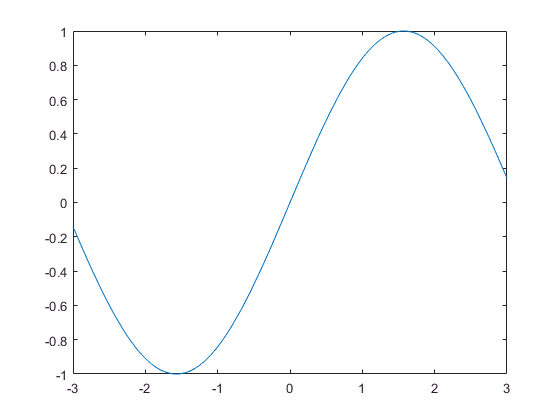

fplot(f(x),[-3,3])

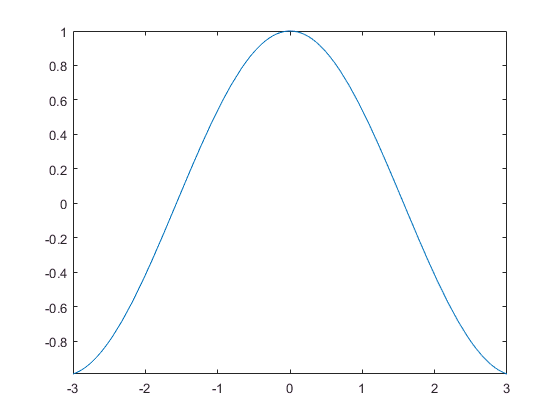

fplot(g(x),[-3,3])

syms a b
expand((a+b)*(a+b))

$$ans = a^{2}+2\,a\,b+b^{2}$$

(a+b)*(a+b)

$$ans = {\left(a+b\right)}^{2}$$

syms x
expand((x-a)^3)

$$ans = -a^{3}+3\,a^{2}\,x-3\,a\,x^{2}+x^{3}$$

simplify((x^2 - 5*x +6)/(x-2))

$$ans = x-3$$

factor(3969000)

ans =      2     2     2     3     3     3     3     5     5     5     7     7


O comando syms define as variáveis simbólicas que serão usadas

solve(x^2 - 5*x +6 == 0,x)

$$ans = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$

syms a b c x
solve(a*x^2 + b*x +c ==0,x)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

syms x
s = solve(abs(x^4-5*x)==1)

$$s = \left(\begin{array}{c} \mathrm{root}\left({z_{1}}^{4}-5\,z_{1}-1,z_{1},1\right)\\ \mathrm{root}\left({z_{1}}^{4}-5\,z_{1}-1,z_{1},2\right)\\ \mathrm{root}\left({z_{1}}^{4}-5\,z_{1}-1,z_{1},3\right)\\ \mathrm{root}\left({z_{1}}^{4}-5\,z_{1}-1,z_{1},4\right) \end{array}\right)$$

vpa(s)

$$ans = \left(\begin{array}{c} -0.7861734859-1.485950402\,\mathrm{i}\\ -0.7861734859+1.485950402\,\mathrm{i}\\ -0.1996820302\\ 1.772029002 \end{array}\right)$$

vpasolve(abs(x^4-5*x)==1)

$$ans = -0.1996820302$$

vpasolve(x^4 - 5 * x == 1)

$$ans = \left(\begin{array}{c} -0.1996820302\\ 1.772029002\\ -0.7861734859-1.485950402\,\mathrm{i}\\ -0.7861734859+1.485950402\,\mathrm{i} \end{array}\right)$$

vpasolve(x^4 - 5 * x == -1)

$$ans = \left(\begin{array}{c} 0.2003220662\\ 1.637305775\\ -0.9188139208+1.484812644\,\mathrm{i}\\ -0.9188139208-1.484812644\,\mathrm{i} \end{array}\right)$$

syms x
f = @(x) abs(x^4 - 5*x) - 1

f = function_handle with value:
    @(x)abs(x^4-5*x)-1


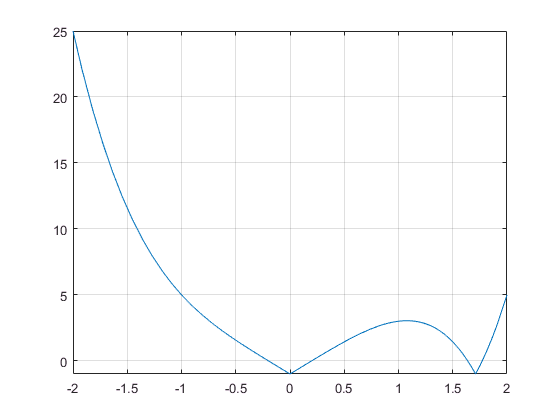

fplot(f(x),[-2,2])
grid on

syms pi
cos(pi)

$$ans = -1$$

sin(pi/4)

$$ans = \frac{\sqrt{2}}{2}$$

pi

$$pi = \pi$$

exp(1)

ans = 2.7183

log(2)

ans = 0.6931

Colocando o comando syms, o valor de pi se torna simbólico e não flutuante.

x = 3

x = 3

y = x^2

y = 9

syms w
z = 3*y - 2*w

$$z = 27-2\,w$$

x

x = 3

clear all

syms x
x

$$x = x$$


syms y
y

$$y = y$$

x = 3

for i= 1:10
    disp(i^2)
end

     1



     4



     9



    16



    25



    36



    49



    64



    81



   100



for i = 1:0.5:10
    disp([i,i^2])
end

     1     1



    1.5000    2.2500



     2     4



    2.5000    6.2500



     3     9



    3.5000   12.2500



     4    16



    4.5000   20.2500



     5    25



    5.5000   30.2500



     6    36



    6.5000   42.2500



     7    49



    7.5000   56.2500



     8    64



    8.5000   72.2500



     9    81



    9.5000   90.2500



    10   100



Lista com o cubo dos 15 primeiros positivos inteiros

for i = 1:15
    disp([i,i^3])
end

     1     1



     2     8



     3    27



     4    64



     5   125



     6   216



     7   343



     8   512



     9   729



          10        1000



          11        1331



          12        1728



          13        2197



          14        2744



          15        3375



Lista com o dobro dos 10 primeiros positivos inteiros

for i=1:10
    disp([i,2*i])
end

     1     2



     2     4



     3     6



     4     8



     5    10



     6    12



     7    14



     8    16



     9    18



    10    20



Os 20 primeiros ímpares

for i=1:2:20
    a=i
    disp(a)
end

a = 1

     1



a = 3

     3



a = 5

     5



a = 7

     7



a = 9

     9



a = 11

    11



a = 13

    13



a = 15

    15



a = 17

    17



a = 19

    19



for i=1:2:20
    disp(i)
end

     1

     3

     5

     7

     9

    11

    13

    15

    17

    19

